Question 2

clear all;
clc
R=8.341/29;
%%Part 1
G=1.4

G = 1.4000

Mdd=2.65

Mdd = 2.6500

Po2bPoa=[];
A0bAc=[];
t=14;
alpha=0;
MAn=[];
for Md=2.4
   
    del=3.5;
    rhs=[];
    lhs=1;
    Sigs=[0:0.1:45];
    for sig=0:0.1:45
        temp=(2*(1+((G-1)/2)*Md^2*(sind(sig))^2)/((G+1)*Md^2*sind(sig)*cosd(sig)))/tand(sig-del);
        
        rhs=[rhs temp];
    end
    threshold=abs(rhs-lhs);
    [~,I]=min(threshold);
    
    finalSig=Sigs(I);
    
    Man=Md*sind(finalSig);
    Mosan=sqrt((Man^2 + 2/(G-1))/((2*G/(G-1))*Man^2 - 1 ));
    
    Mosa=Mosan/sind(finalSig-del);
    
    %%Part 2
    G=1.4;
    finalM=-100;
    Mos=Mosa;
    Gmos=((G+1)/(G-1))^0.5*atan((((G-1)/(G+1))*(Mos^2-1))^0.5)-atan((Mos^2-1)^0.5);
    theta=15;
    Gm1 = Gmos - (theta*3.14)/180;
    rhs=[];
    lhs=Gm1;
    Ms=[0:0.001:4];
    for M=0:0.001:4
        temp=((G+1)/(G-1))^0.5*atan((((G-1)/(G+1))*(M^2-1))^0.5)-atan((M^2-1) ^ 0.5);
        
        rhs=[rhs temp];
    end
    
    threshold=abs(rhs-lhs);
    [~,I]=min(threshold);
    
    finalM=Ms(I);
    
    %disp(['Sigma ',num2str(finalSig),' M1 ',num2str(finalM)]);
    M1p=sqrt((finalM^2 + 2/(G-1))/((2*G/(G-1))*finalM^2 - 1 ));

    if Md<=Mdd
        Po1bPoa=(((((G+1)/2)*(Man^2))/(1+(((G-1)/2)*(Man^2))))^(G/(G-1)))/((((2*G)/(G+1))*(Man^2))-((G-1)/(G+1)))^(1/(G-1));%Poy/PoO
        Po1pbPo1=(((((G+1)/2)*(finalM^2))/(1+(((G-1)/2)*(finalM^2))))^(G/(G-1)))/((((2*G)/(G+1))*(finalM^2))-((G-1)/(G+1)))^(1/(G-1));%Poy/PoO
        
        po2bpo1 = 0.95;% b=0.95||po2/po1=0.95
        temp=Po1bPoa * Po1pbPo1 * po2bpo1;
        disp(['Md ',num2str(Md),' Po2/Poa ',num2str(temp)])
        Po2bPoa = [Po2bPoa temp];
        PbPom1=(1+((G-1)/2)*finalM^2)^-(G/(G-1))*((G/R)^0.5*finalM*(1+((G-1)/2)*finalM^2)^0.5);
        PbPoma=(1+(G-1)/2*Md^2)^-(G/(G-1))*((G/R)^0.5*Md*(1+((G-1)/2)*Md^2)^0.5);
        tt=(Po1bPoa)*(PbPom1/PbPoma)*(0.519);
       A0bAc=[A0bAc tt];
    else
        Mdpo2bpoa=Po2bPoa(1,66);
        temp=Mdpo2bpoa*exp(0.96*(Mdd-Md));% b=0.96 l/h=4
        Po2bPoa = [Po2bPoa temp];
         tt=sind(t+alpha)/sind(t);
        A0bAc=[A0bAc tt]; 
    end
end

Md 2.4 Po2/Poa 0.8065


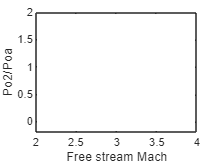

Md=[2:0.01:4];
plot(Md,Po2bPoa)
xlabel('Free stream Mach')
ylabel('Po2/Poa')

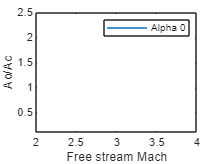

plot(Md,A0bAc)
xlabel('Free stream Mach')
ylabel('Ao/Ac')

legend('Alpha 0')
ylim([0.1,2.5])